# Pendolo Invertito

Iniziamo settando i parametri del sistema ad alcuni valori iniziali:

clear;
clearvars;
%x,t,m,M,l,F
dt = (0:0.05:20);
m = 0.1;%kg
M = 1;%kg
l = 0.5;%m
F = 1;%N
g = 9.81; %m/s^2

Infine le condizioni iniziali e la precisione del risolutore:

x0 = [0,0,0,0];% theta_0 = 0, velocità angolare = 0 posizione iniziale=0
% velocità iniziale 0 m/s
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

Chiamiamo ora il nostro ode45:

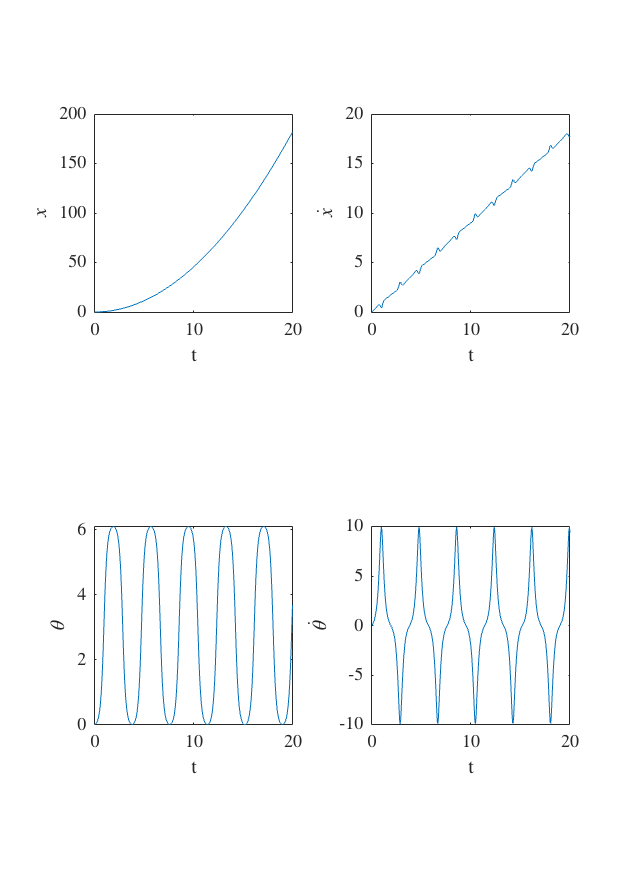

[t,x] = ode45(@(t,x)Inv_pend(x,t,m,M,l,F),dt,x0,opts);
prima_ris = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
subplot(2,2,1)
plot(t,x(:,3))
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$x$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
subplot(2,2,2);
plot(t,x(:,4))
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{x}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
subplot(2,2,3);
plot(t,x(:,1));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\theta$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
subplot(2,2,4);
plot(t,x(:,2));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
exportgraphics(prima_ris,'prima_ris.eps','Resolution',300);

Andiamo ora a fare uno studio parametrico del nostro sistema:

dt = (0:0.05:20);
C = {'k','b','r'}; % Cell array of colros.
studio_param = figure;
sgtitle('$l \quad\quad\quad\quad\quad\quad   m \quad\quad\quad\quad\quad\quad M \quad\quad\quad\quad\quad\quad  F$','Interpreter','latex');
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
k = 1;
for i= 1:4
    % i varia tra le gradezze da riportare
    

    if (i ~= 1)
        k = 4*(i-1)+1;
    end
    index = i-1;
    while k<=4*index+4
       
        %l
        l_val = [1 5 10];
        subplot(4,4,k);
        for j = 1:length(l_val)
        [t,x_j] = ode45(@(t,x)Inv_pend(x,t,m,M,l_val(j),F),dt,x0,opts);
        [x_pulito,b] =  rmoutliers(x_j(:,i)); %a ripulito b vettore logico
        %t_pulito ha le dimensioni di a
        t_pulito = t(~b) ;
        plot(t_pulito,x_pulito,'color',C{j});
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
            if j ==1
                hold on;
            end
        end
            %Ylabel 
            if k == 1
                ylabel ('$x(t)$','Interpreter','latex','FontSize',14);
            end
            if k == 5
                ylabel ('$\dot{x}(t)$','Interpreter','latex','FontSize',14);
            end
             if k == 9
                ylabel ('$\theta(t)$','Interpreter','latex','FontSize',14);
            end
             if k == 13
                ylabel ('$\dot{\theta}(t)$','Interpreter','latex','FontSize',14);
             end
            k = k+1;

        %m
        m_val = [0.1 1 4];
        subplot(4,4,k);
        for j = 1:length(m_val)
        [t,x_j] = ode45(@(t,x)Inv_pend(x,t,m_val(j),M,l,F),dt,x0,opts);
        [x_pulito,b] =  rmoutliers(x_j(:,i)); %a ripulito b vettore logico
        %t_pulito ha le dimensioni di a
        t_pulito = t(~b) ;
        plot(t_pulito,x_pulito,'color',C{j});
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
            if j ==1
                hold on;
            end
        end
        k = k+1;

        %M
        M_val = [1 3 5];
        subplot(4,4,k);
        for j = 1:length(M_val)
        [t,x_j] = ode45(@(t,x)Inv_pend(x,t,m,M_val(j),l,F),dt,x0,opts);
        [x_pulito,b] =  rmoutliers(x_j(:,i)); %a ripulito b vettore logico
        %t_pulito ha le dimensioni di a
        t_pulito = t(~b) ;
        plot(t_pulito,x_pulito,'color',C{j});
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
            if j ==1
                hold on;
            end
        end
        k = k+1;

        %F
        F_val = [1 3 5];
        subplot(4,4,k);
        for j = 1:length(F_val)
        [t,x_j] = ode45(@(t,x)Inv_pend(x,t,m,M,l,F_val(j)),dt,x0,opts);
        [x_pulito,b] =  rmoutliers(x_j(:,i)); %a ripulito b vettore logico
        %t_pulito ha le dimensioni di a
        t_pulito = t(~b) ;
        plot(t_pulito,x_pulito,'color',C{j});
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
            if j ==1
                hold on;
            end
        end
          k = k+1;
    end
    
end
%exportgraphics(f,'studio_param.eps','Resolution',300);